Run graphics export and animation from the Command Window; Live Editor export can block. Run runMeFirst in the package root, then add the chosen example folder or make it Current Folder before calling a .m example by name.

Note: Force convention: getForce(g,t,F) uses a unit normal and a user-specified signed force F. F=1 is a unit-force example; this Live Script also uses F=2 and F=0.3. No physical force unit is imposed. The moment unit is force times the module length unit. plotForce uses F as a signed arrow length in plot coordinates.

# gear — Individual gear (v21)

gears v21 — Public interface guide.

Run runMeFirst once from the package root before running this Live Script. The bundled draw*/gk* routines and int2crv are private implementation helpers in classes/private; do not add that folder to the MATLAB path.

See examples/README.md for the scripts. Relative outputs use Current Folder; output methods create missing parent folders. Cached Live Script outputs are retained from the supplied archive and have not been regenerated. Run sections in order for current results.

Use public plot/animate/print methods. For plots: 'title',on/off/1/0/true/false; 'save',filename or 'save',[] for the default JPG. Names without '-' are preferred; the old prefix remains accepted.

A handle object generated from a fixed gearRack. Each gear has its own independent x and u; changing g.u does not alter the rack or another gear.

## **Syntax**

g = gear(rack,z)

g = gear(rack,z,'beta',beta)

g = gear(rack,z,'x',x,'u',u)

g = gear(rack,z,'np',np,'sampling','heun')

## **Description**

gear(rack,z) constructs a gear with an integer z>1. Construct separate objects for independent gears; assignment shares a handle.

'beta' specifies the helix-angle magnitude in degrees.

'x' specifies profile shift; 'u' specifies the per-gear tip-shortening coefficient.

'np' controls profile sampling; 'sampling' selects heun (default) or euler.

## **Input arguments**

**rack - the unchanged basic gearRack object; it may be shared between gears.**

z - integer number of teeth, z>1.

## Optional input name-value arguments

'beta',beta - nonnegative helix-angle magnitude in degrees, below 90; default 0.

'x',x - profile-shift coefficient; default 0.

'np',np - sampling control, constructor range 4..100, default 100; 'u',u - tip-shortening coefficient, default 1, 0<u<=1. 'q',q - minimum tip/reference thickness ratio, default 0.2, 0<q<1.

## Properties 

    beta -  the helix angle in degrees

    z      - number of teeth

    x      - profile shift coefficient

np - sampling-density control, not an exact vertex count. Constructor/gearContour range: 4..100; assignment to g.np: 10..200.

Ri - bore radius, default 0, with 0<=Ri<g.Rd. Used for gear3d display; not a tooth-generation parameter.

u - independent tip-shortening coefficient; set with the gear constructor or g.u=value.

sampling and profileInfo - sampling method and retained-segment diagnostics. q is the tip/reference thickness criterion; umax is its calculated upper u limit. u=calcU(g) uses g.q; u=calcU(g,q) uses a temporary ratio. These queries do not change g; apply with g.u=g.umax.

## **Properties (dependent)**

**R0 - normal-system reference radius**

Ra - nominal tip-circle radius; the retained pointed tip can end at Rc below Ra.

Rr - transverse reference pitch radius

Ru - radius at the retained involute/fillet transition

        Rb   -- base circle radius

        Rd   -- dedendum (root) circle radius

        e    -- profile shift

h - retained total tooth height: h=ha+hd; for a pointed tip, h=Rc-Rd.

ha - retained addendum height: Ra-Rr, or Rc-Rr for a pointed tip.

hd - dedendum height: Rr-Rd, including the root fillet. Ru is the involute/fillet junction.

        sa   -- tooth thickness at the addendum circle        

        sr   -- tooth thickness at the reference pitch circle       

su - tooth thickness at the retained involute/fillet transition

        sb   -- tooth thickness at the base circle     

sd - tooth thickness at the root circle.

        xmax -- max. profile shift coefficient to avoid pointed teeth

        xmin -- min. profile shift coefficient to avoid undercutting

zmin - zero-shift no-undercut tooth-count threshold.

        L    - length of segments: L(1) - tip arc, L(2) - involute, L(3) - fillet, L(4) - root arc

        Lt   -- total length of profile

## **Object functions**

#### [X,Y,info] = gearContour(g,'file',filename,'np',20,'sampling','heun')

Returns a closed contour X/Y and optional diagnostics. A character filename exports planar tab-delimited XYZ coordinates, Z=0, with four significant digits. Missing parent folders are created; existing files can be overwritten. Returned arrays retain numerical precision. np controls spacing, not the total vertex count.

#### **    plot(obj,varargin) - **

**        Input:**

        Optional input pairs:

'fig',number - figure selection

'nz',nz - number of teeth to draw

        Options:

            'keep' - keep previous figure

            {'nocir','nocirc'} - do not draw circles

            {'nocent','nocenter','nocen'} - do not draw center point

            {'notxt','notext'} - do not add title

'save',filename or 'save',[] - named/default JPG; 'title',false hides the title.

            'gen' - plot generation of gear tooth

#### **    print(obj,[fid])   **

**print(g) prints to Command Window; print(g,fid) accepts an open text-file identifier, not a filename.**

#### **plotRackContactPts(g,'title',false,'save',filename)**

        plot rack tooth with marked contact regions

**    plotNormal(obj,t,ts,te,plotOpt)**

Draw the normal at t in [0,1], where t=0 is the retained tip and t=1 the retained root. ts,te specify the endpoints along the normal; plotOpt contains line/display options.

**    plotTangent(obj,t,ts,te,plotOpt)**

Draw the tangent at t in [0,1], where t=0 is the retained tip and t=1 the retained root. ts,te specify the endpoints along the tangent; plotOpt contains line/display options.

    **plotForce(obj,t,F,plotOpt)**

Draw a normal-force arrow at t; F is a signed arrow length in plot coordinates.

s = getData(obj,t), 0<=t<=1: geometric data on the retained involute; t=0 at the tip, t=1 at the root. getPar(obj,R) returns the corresponding normalised parameter or NaN if the solve fails.

          s.X,s.Y - point on involute

          s.R     - radius

          s.s      - thickness

          s.L     - =sqrt(R^2 - Rb^2)

s.phi - polar-angle value returned by getData, in degrees

s.th - local involute pressure angle, in degrees

s.invth - involute-function value expressed in degrees

**    [x,y,nx,ny] = getNormal(obj,t) **

Return the point x,y and unit normal nx,ny at the retained involute parameter t in [0,1]; nx^2+ny^2=1.

**[x,y,tx,ty] = getTangent(obj,t) **

Return the point x,y and unit tangent tx,ty at the retained involute parameter t in [0,1]; tx^2+ty^2=1.

**[x,y,Fx,Fy,M] = getForce(obj,t,F) **

Return the point x,y, signed normal-force components Fx,Fy and moment M about the gear centre. hypot(Fx,Fy)=abs(F); M=x*Fy-y*Fx. No force unit is imposed.

## **Examples**

% Run runMeFirst once before this Live Script; private helpers are bundled.
clear all; close all; clc
% Outputs use pwd. No output directories are created by setup.
%assert(~isempty(which('gear')),'Run runMeFirst first.');


## **Example 1**

% define rack
a = gearRack(2)

a =   gearRack with properties:

    alpha: 20
        m: 2
        c: 0.1670


print(a)

Gear rack data
                                    Module:            2.0000       mm
                            Pressure angle:            20:00:00
                       Tip tooth clearance:            0.1670       mm
Calculated parameters
                              Filet radius:            0.5076       mm
                                     Point:      xx          yy 
                                        #1:      0.0000      2.0000 mm
                                        #2:      0.8429      2.0000 mm
                                        #3:      2.2987     -2.0000 mm
                                        #4:      2.7757     -2.3340 mm
                             Fillet center:      2.7757     -1.8264 mm
                                   Segment:            Length
                                        #1:            0.8429       mm
                                        #2:            4.2567       mm
                                        #3:            0.6202 

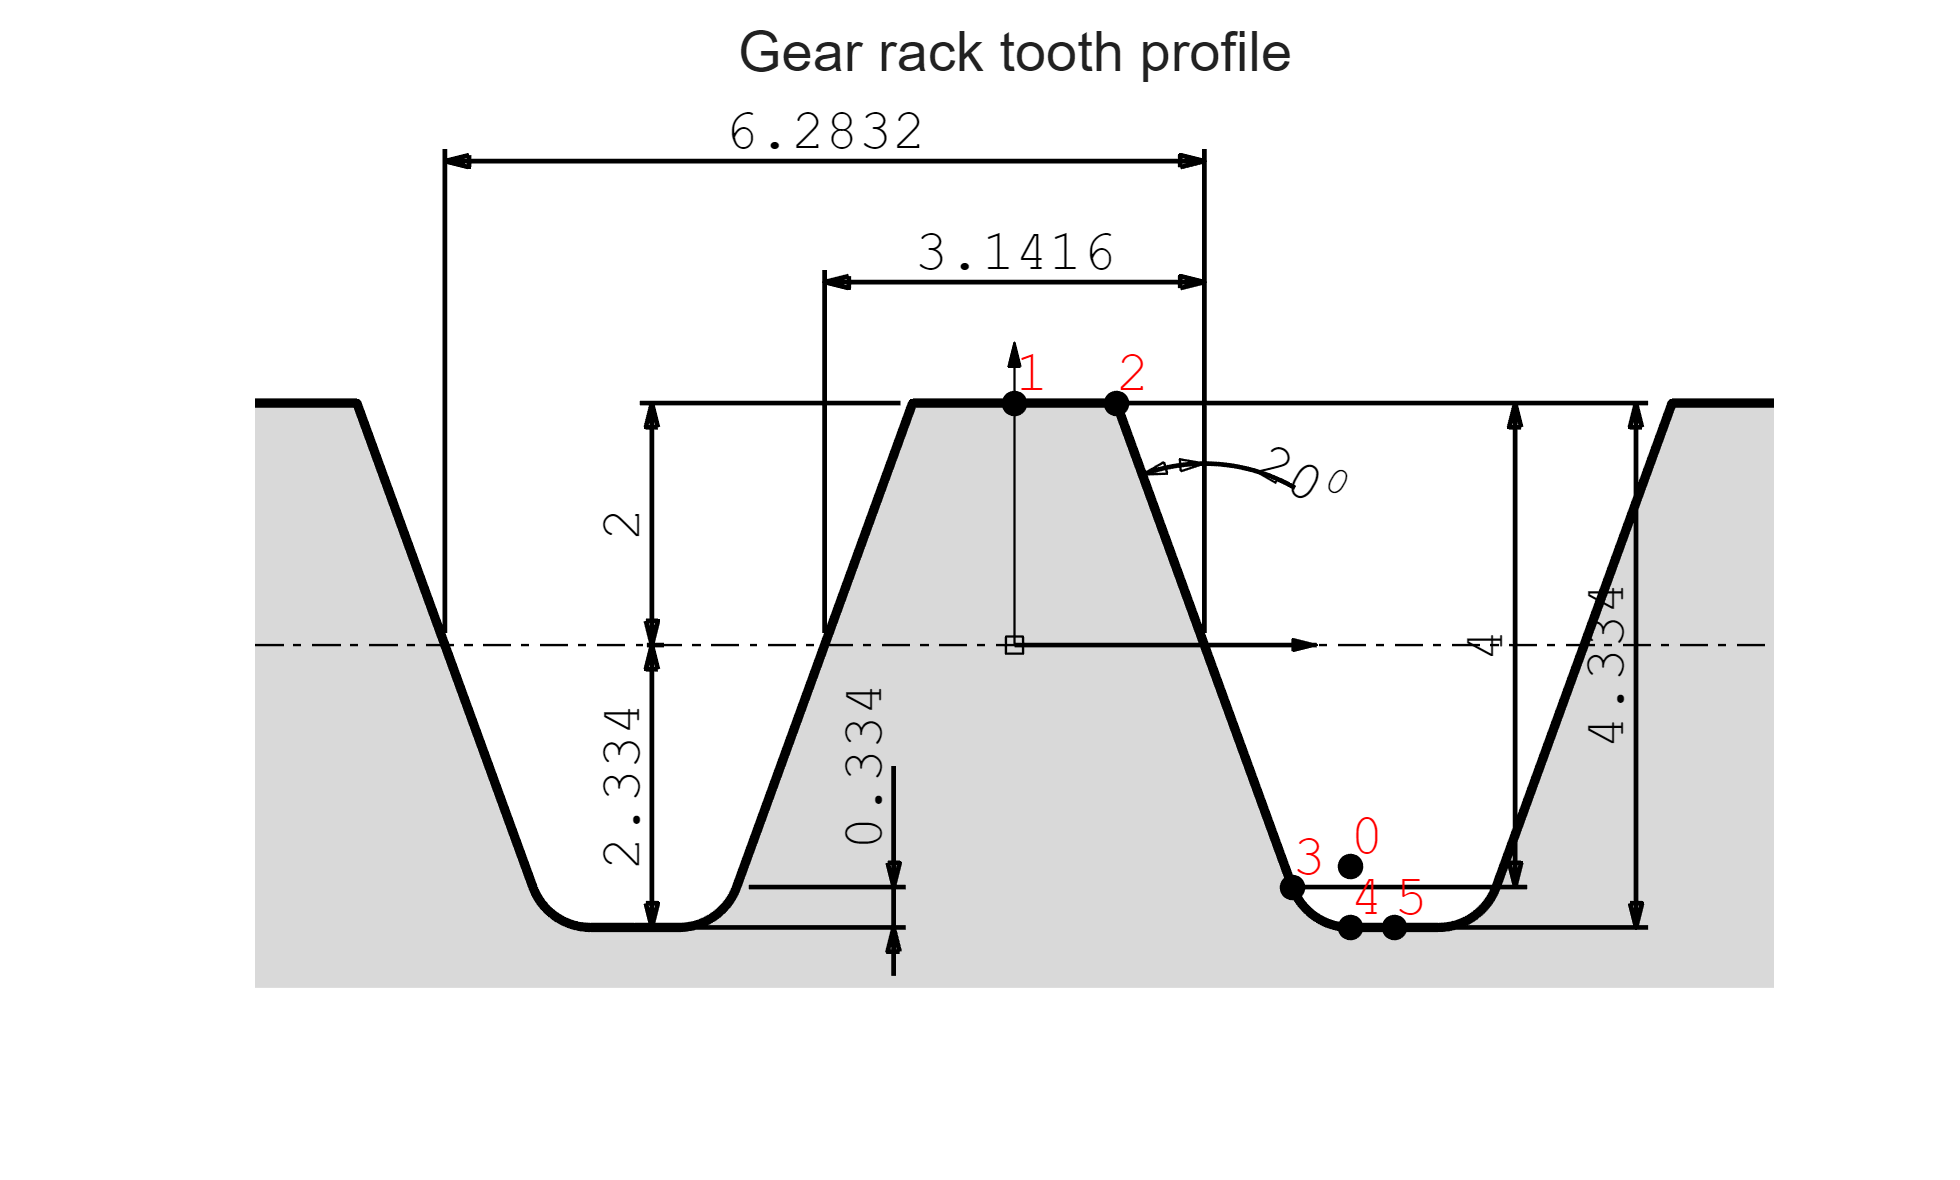

% plot rack
plot(a)

% define gear with 8 tooth and profile shift 0
g1 = gear(a,8,'x',0,'beta',0)

g1 =   gear with properties:

              q: 0.2000
              z: 8
              x: 0
           beta: 0
              u: 1
           umax: 1
             Ri: 0
             np: 100
       sampling: 'heun'
    profileInfo: [1×1 struct]
           rack: [1×1 gearRack]
             R0: 8
             Rc: 10.5958
             Ra: 10
             Rr: 8
             Ru: 7.6126
             Rb: 7.5175
             Rd: 5.6660
              e: 0
              h: 4.3340
             ha: 2
             hd: 0.3874
             sa: 1.0825
             sr: 3.1416
             su: 3.1961
             sb: 3.1762
             sd: 3.9318
           xmax: 1.1325
           xmin: 0.5321
           zmin: 17.0973
              L: [4×1 double]
             Lt: 6.0183
           tpar: [4×2 double]
             tc: 0.0955


% print data
print(g1)

Data
                               Number of teeth:           8
                                        Module:      2.0000 mm
                       Standard pressure angle:    20:00:00 
             Manufacturing tip tooth clearance:      0.1670 mm
                The tip shortening coefficient:      1.0000 
                                   Helix angle:     0:00:00 
                    Profile shift coefficients:      0.0000
Calculated parameters
                Addendum (tip) circle diameter:     20.0000 mm
               Reference pitch circle diameter:     16.0000 mm
                      Undercut circle diameter:     15.2251 mm
                          Base circle diameter:     15.0351 mm
               Dedendum (root) circle diameter:     11.3320 mm
                            Total tooth height:      4.3340 mm
                         Addendum tooth height:      2.0000 mm
                         Dedendum tooth height:      0.3874 mm
        Tooth thickness at the addendum 

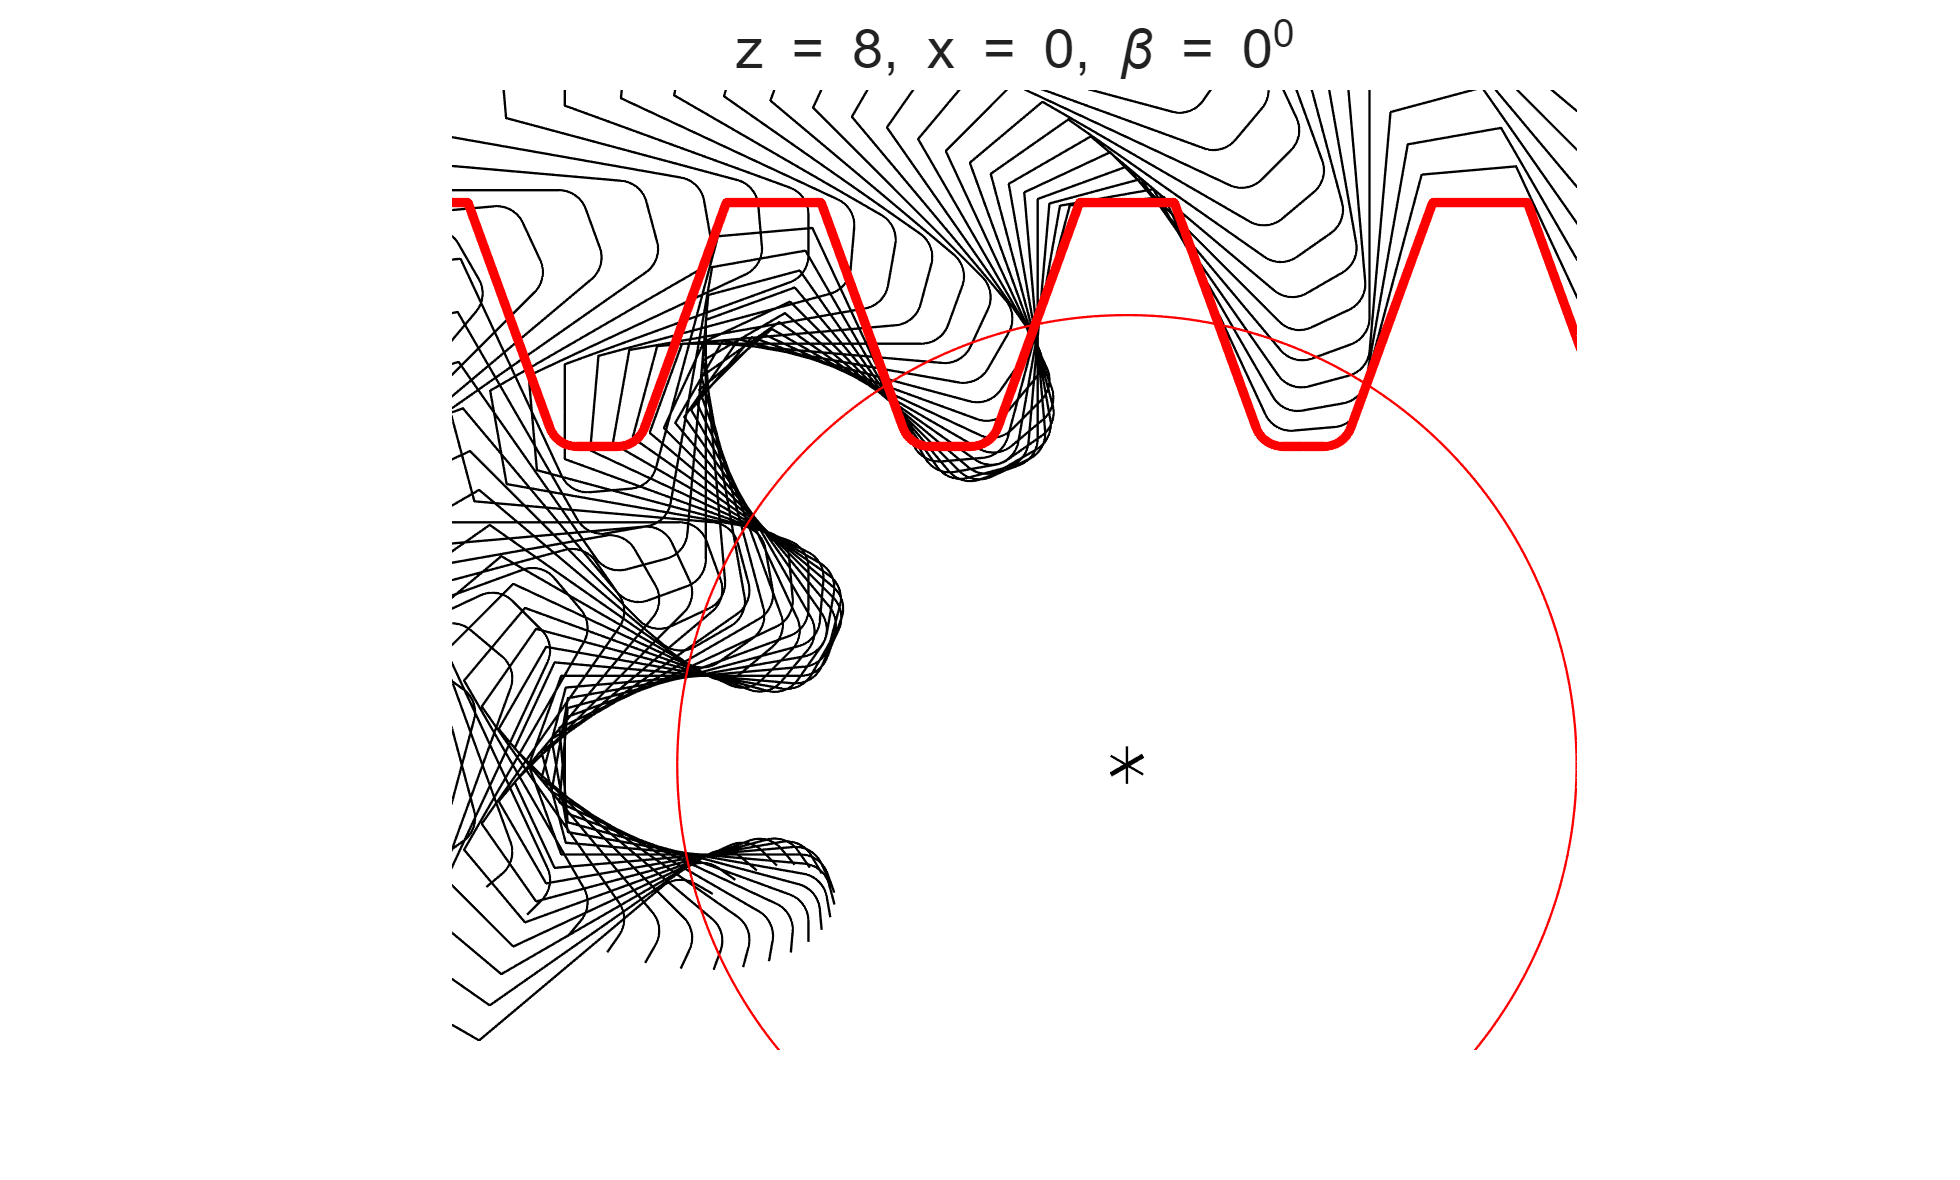

% plot gear formation by rooling rack
gearGenerating(g1.rack,8); %,'save','rack7','title',0)

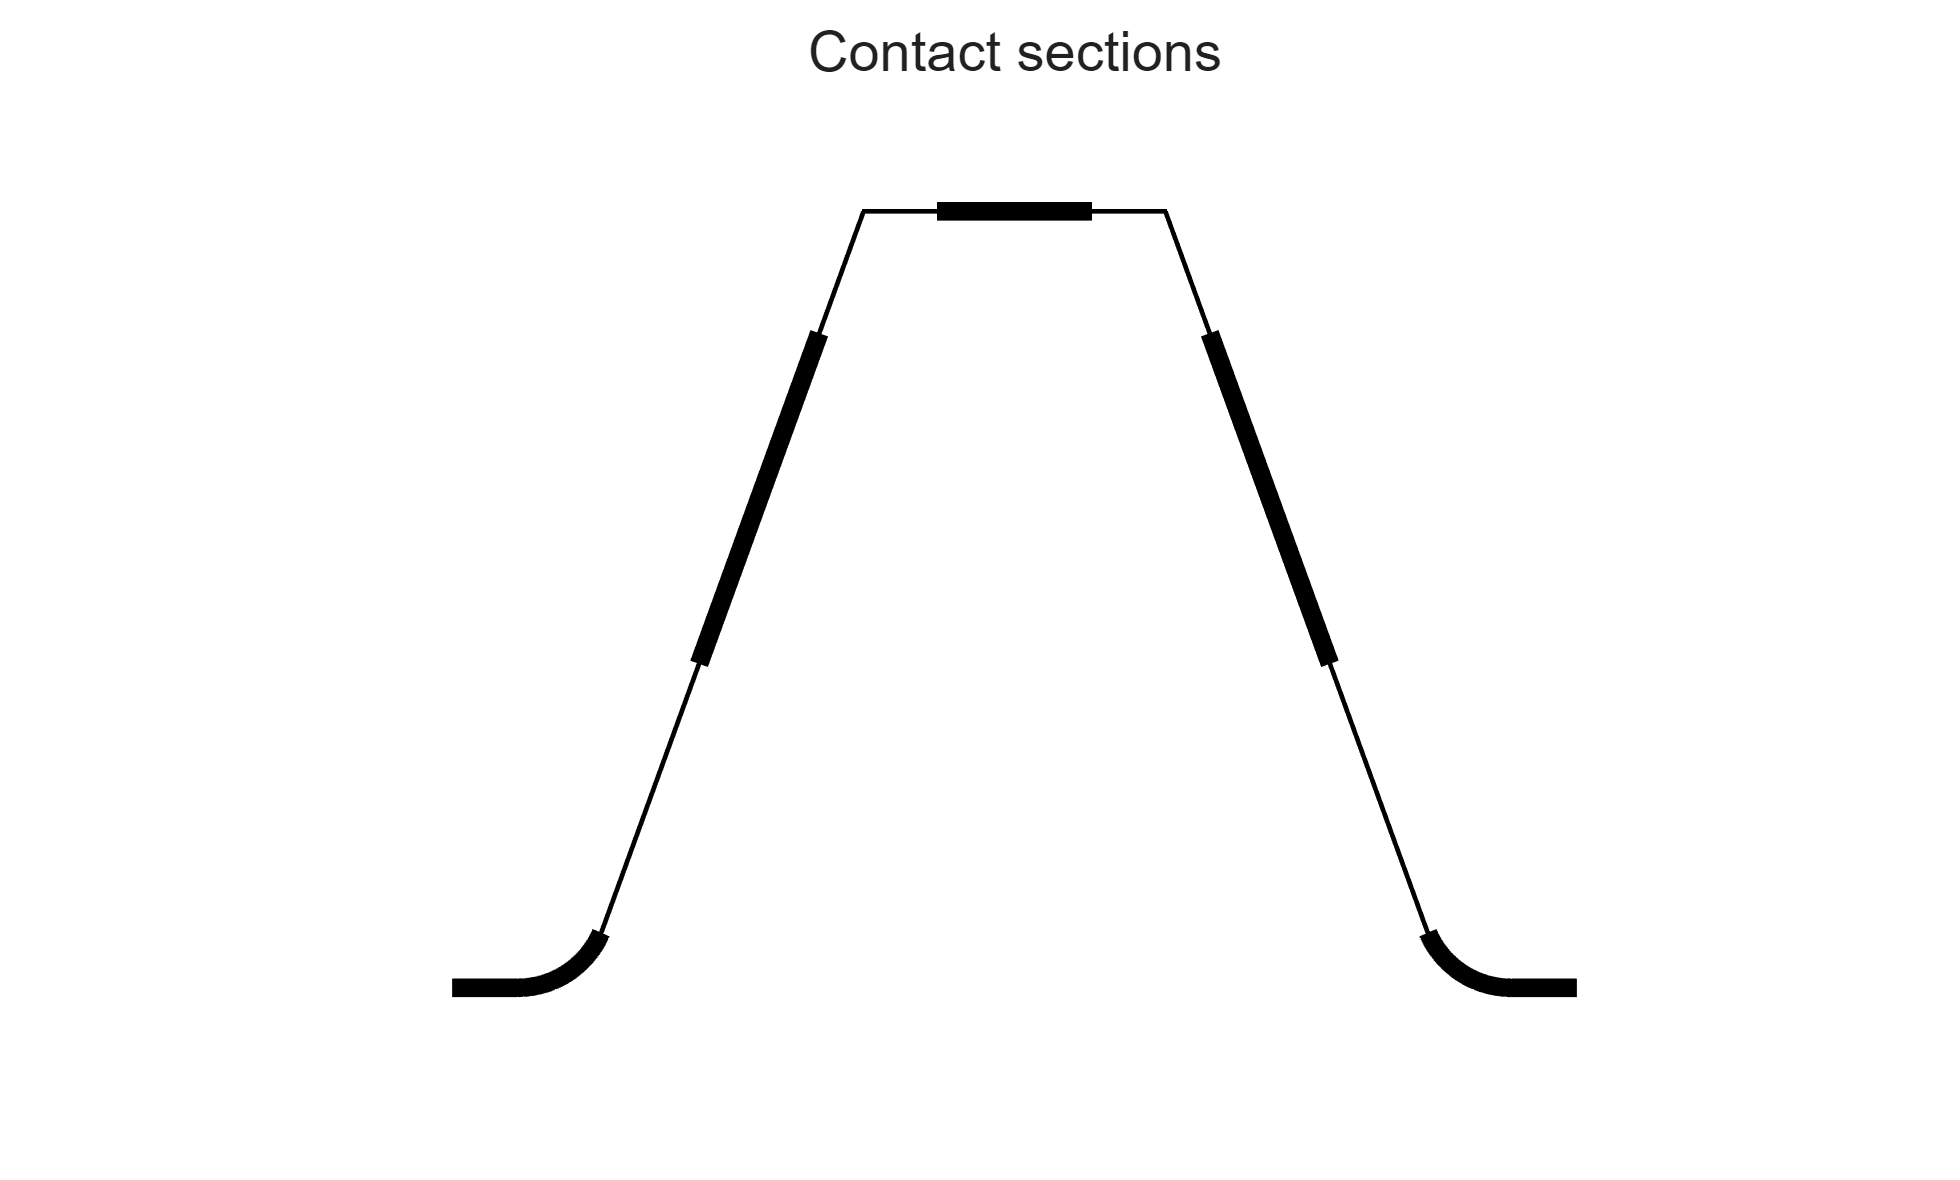

% plot contact regions on rack
plotRackContactPts(g1); %,'save','section7','title',0)

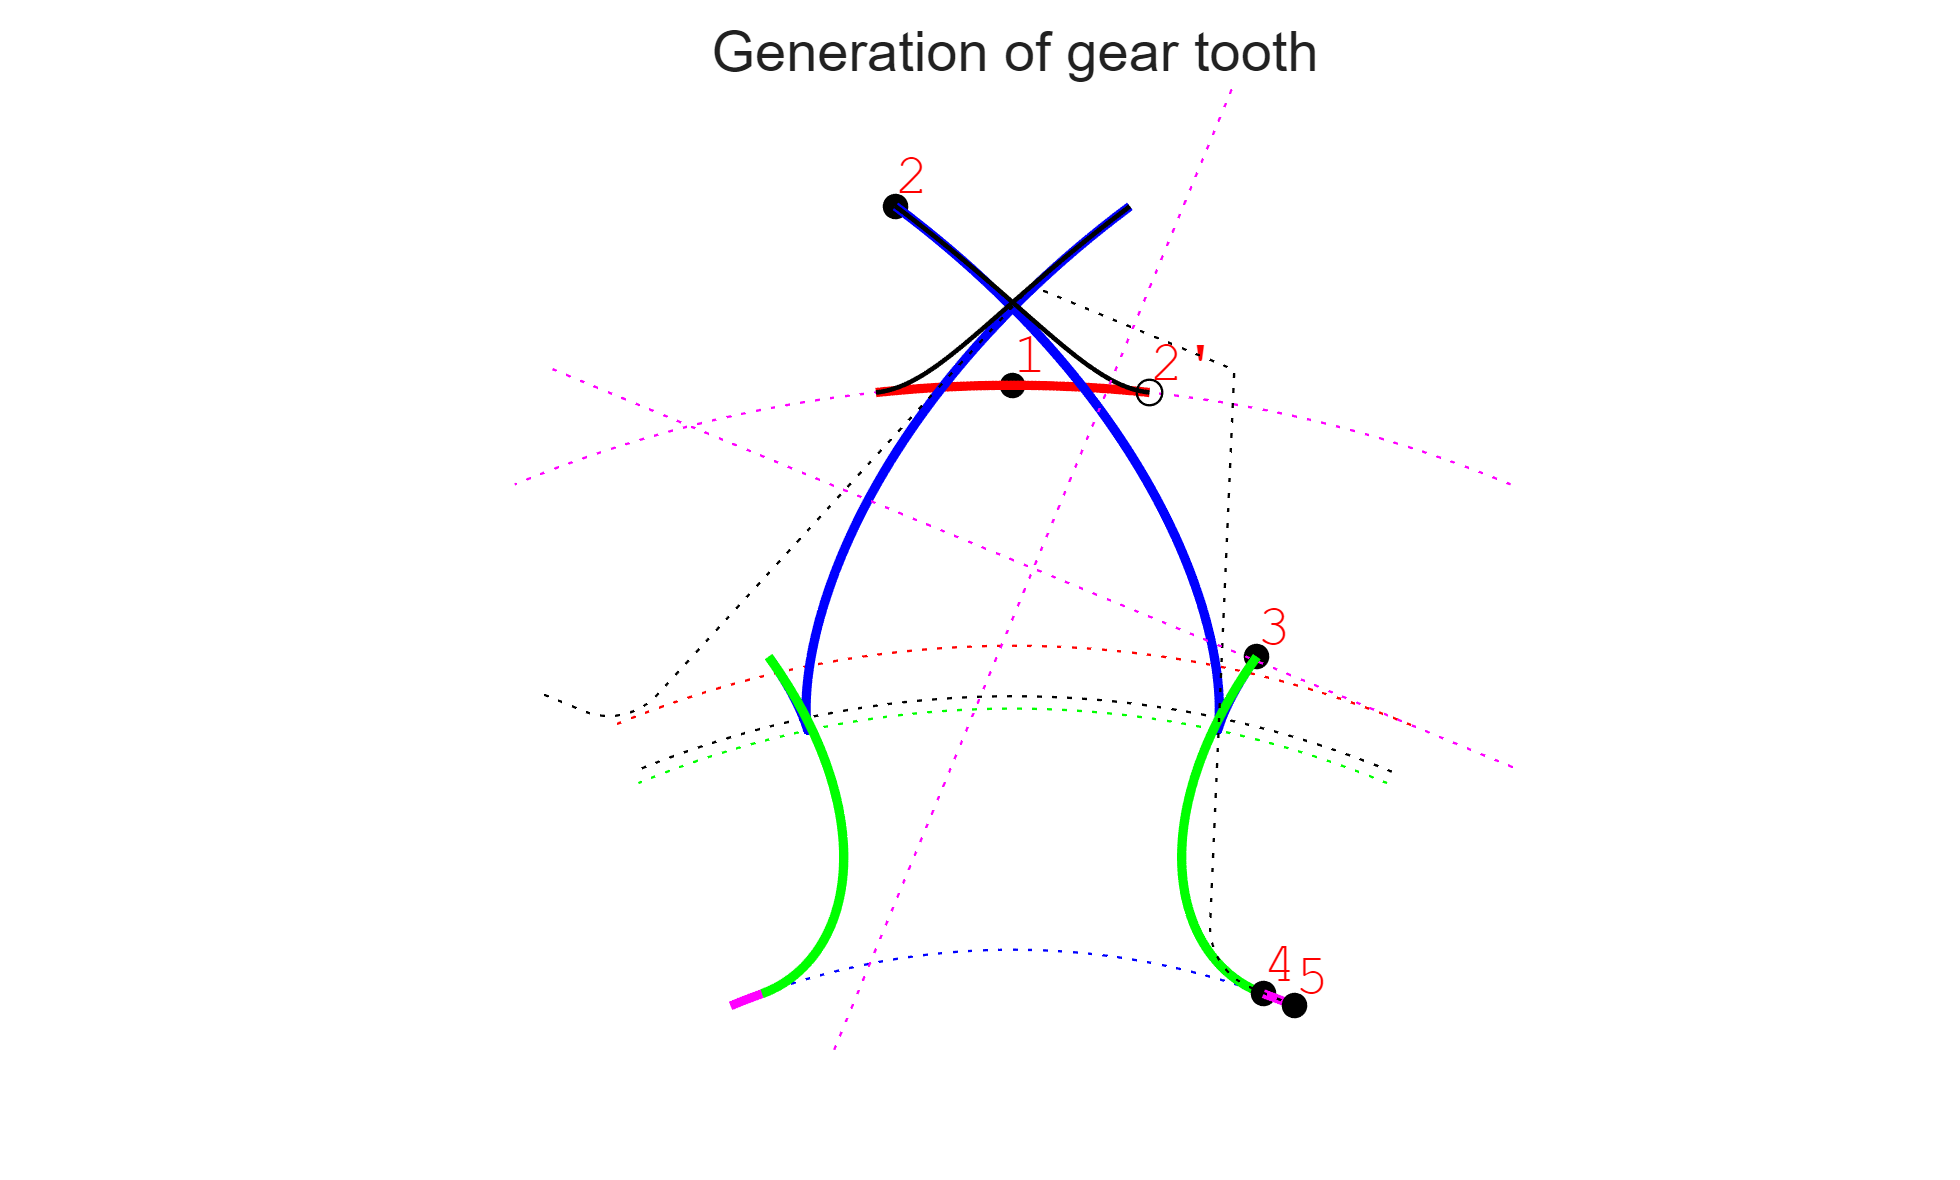

% plot gear formation
plot(g1,'gen') % ,'save','tooth7','title',0)

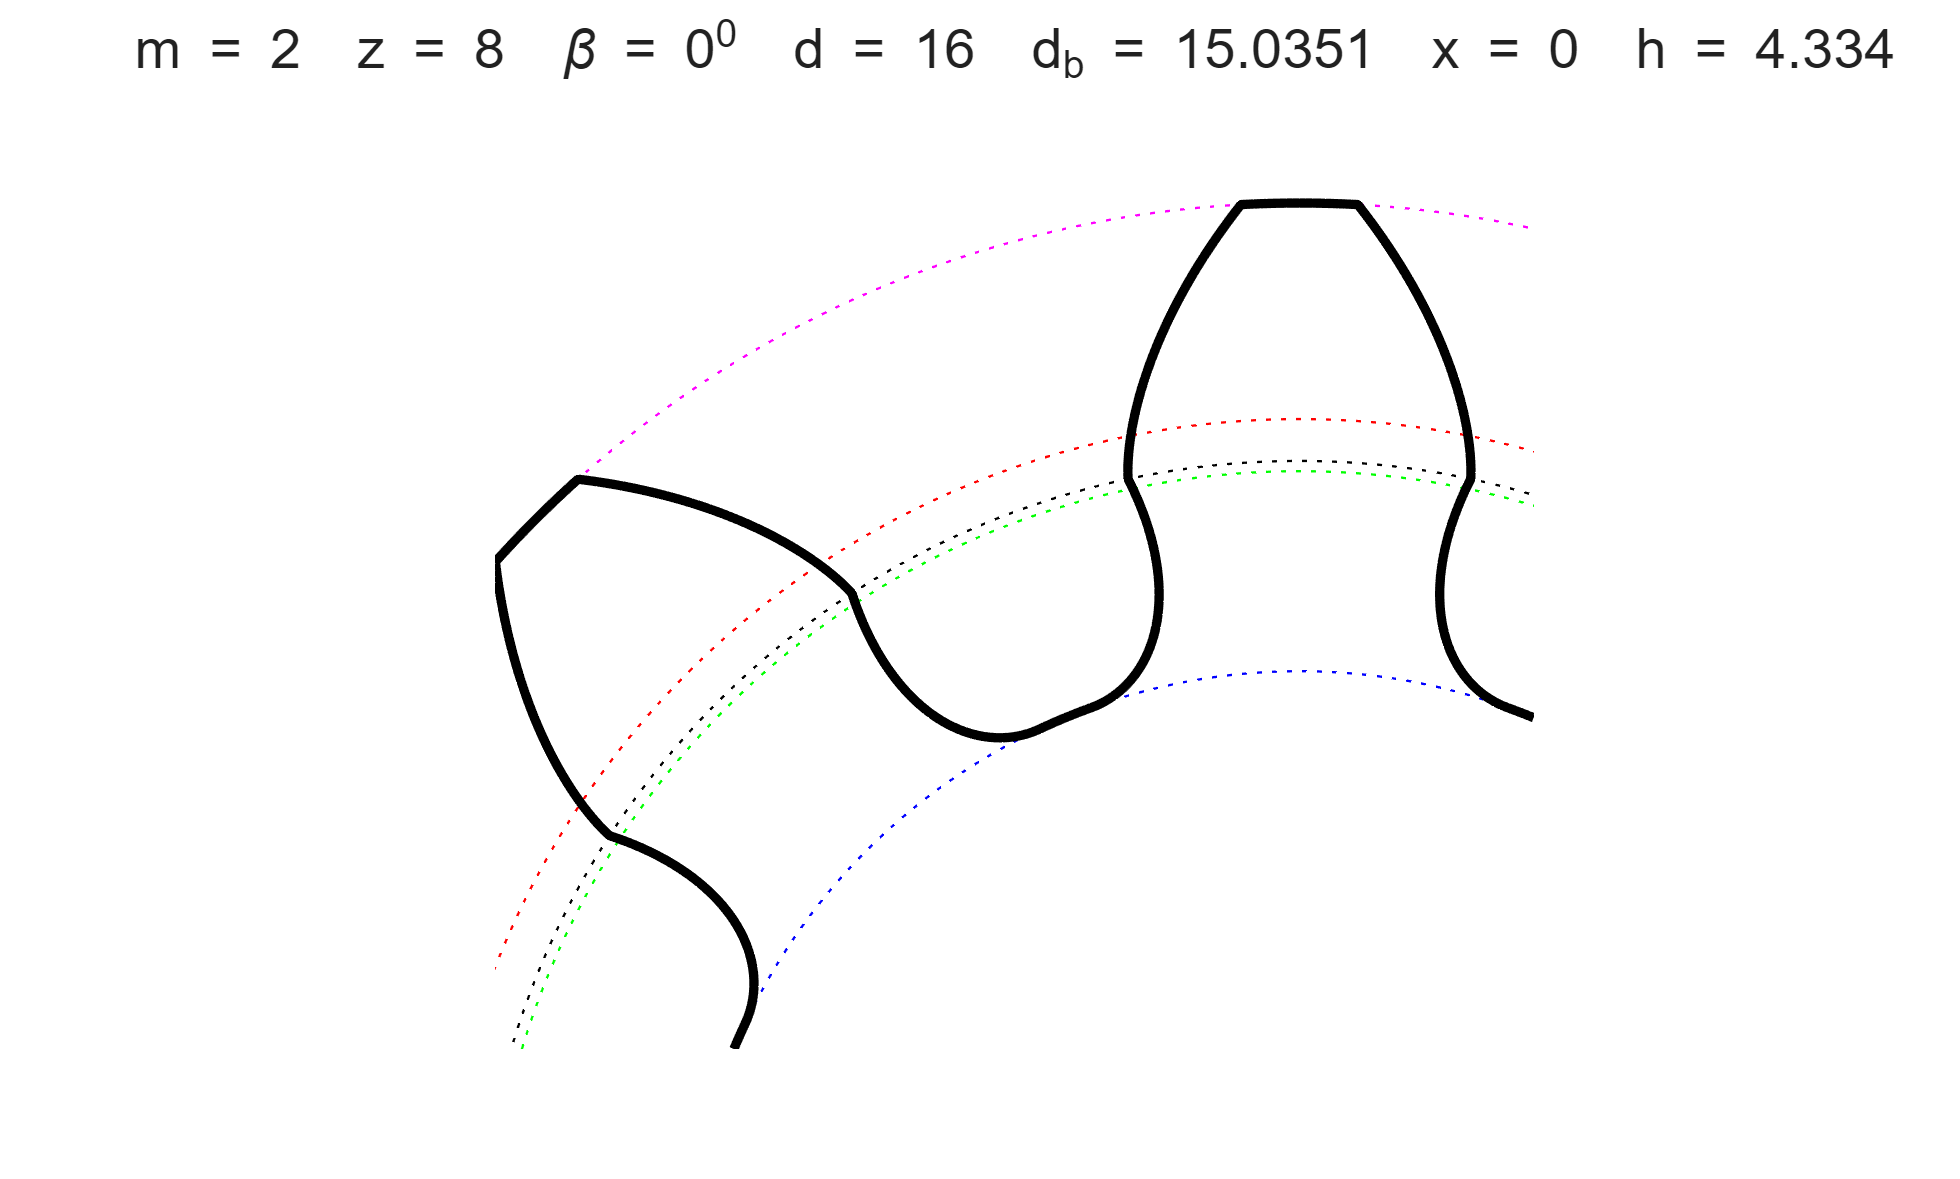

% plot 2 tooth of gear
plot(g1,'-nz',2); %,'save','gear70','title',0)

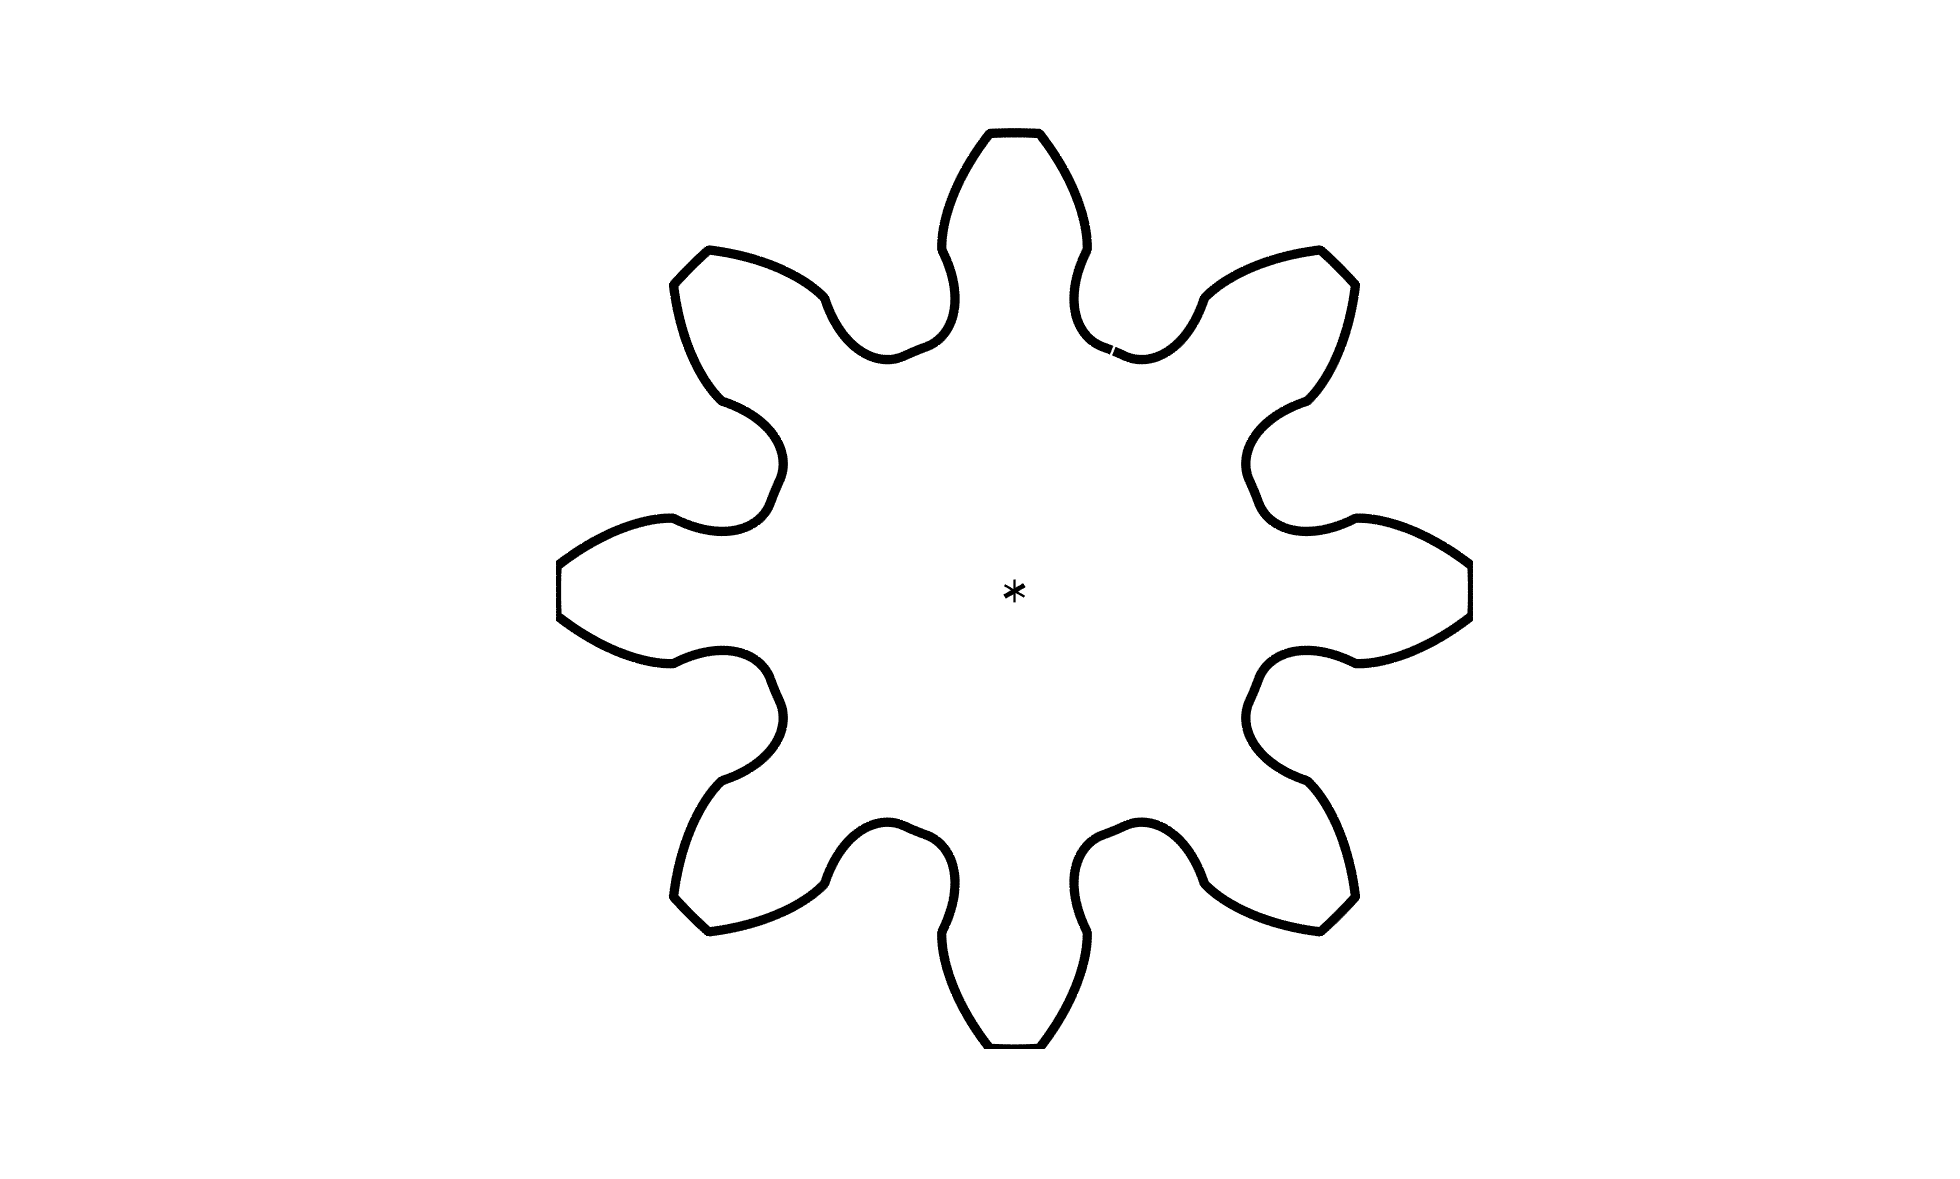

% plot complt gear without circles
plot(g1,'nocir','title',0)

## Example 2: five-tooth helical gear; the separate rack-position display below uses eight teeth.

% define 8-tooth gear with module 1 mm and alpha 15 degrees
b = gear(gearRack(1,'alpha',15),5,'x',0,'beta',10)

b =   gear with properties:

              q: 0.2000
              z: 5
              x: 0
           beta: 10
              u: 1
           umax: 1
             Ri: 0
             np: 100
       sampling: 'heun'
    profileInfo: [1×1 struct]
           rack: [1×1 gearRack]
             R0: 2.5000
             Rc: 3.8156
             Ra: 3.5386
             Rr: 2.5386
             Ru: 2.5967
             Rb: 2.4495
             Rd: 1.3716
              e: 0
              h: 2.1670
             ha: 1
             hd: -0.0582
             sa: 0.5965
             sr: 1.5950
             su: 1.5947
             sb: 1.5706
             sd: 1.3946
           xmax: 0.4186
           xmin: 0.8250
           zmin: 28.5756
              L: [4×1 double]
             Lt: 3.1277
           tpar: [4×2 double]
             tc: 0.2035


% print data
print(b)

Data
                               Number of teeth:           5
                                        Module:      1.0000 mm
                       Standard pressure angle:    15:00:00 
             Manufacturing tip tooth clearance:      0.1670 mm
                The tip shortening coefficient:      1.0000 
                                   Helix angle:    10:00:00 
                    Profile shift coefficients:      0.0000
Calculated parameters
                Addendum (tip) circle diameter:      7.0771 mm
               Reference pitch circle diameter:      5.0771 mm
                      Undercut circle diameter:      5.1935 mm
                          Base circle diameter:      4.8990 mm
               Dedendum (root) circle diameter:      2.7431 mm
                            Total tooth height:      2.1670 mm
                         Addendum tooth height:      1.0000 mm
                         Dedendum tooth height:     -0.0582 mm
        Tooth thickness at the addendum 

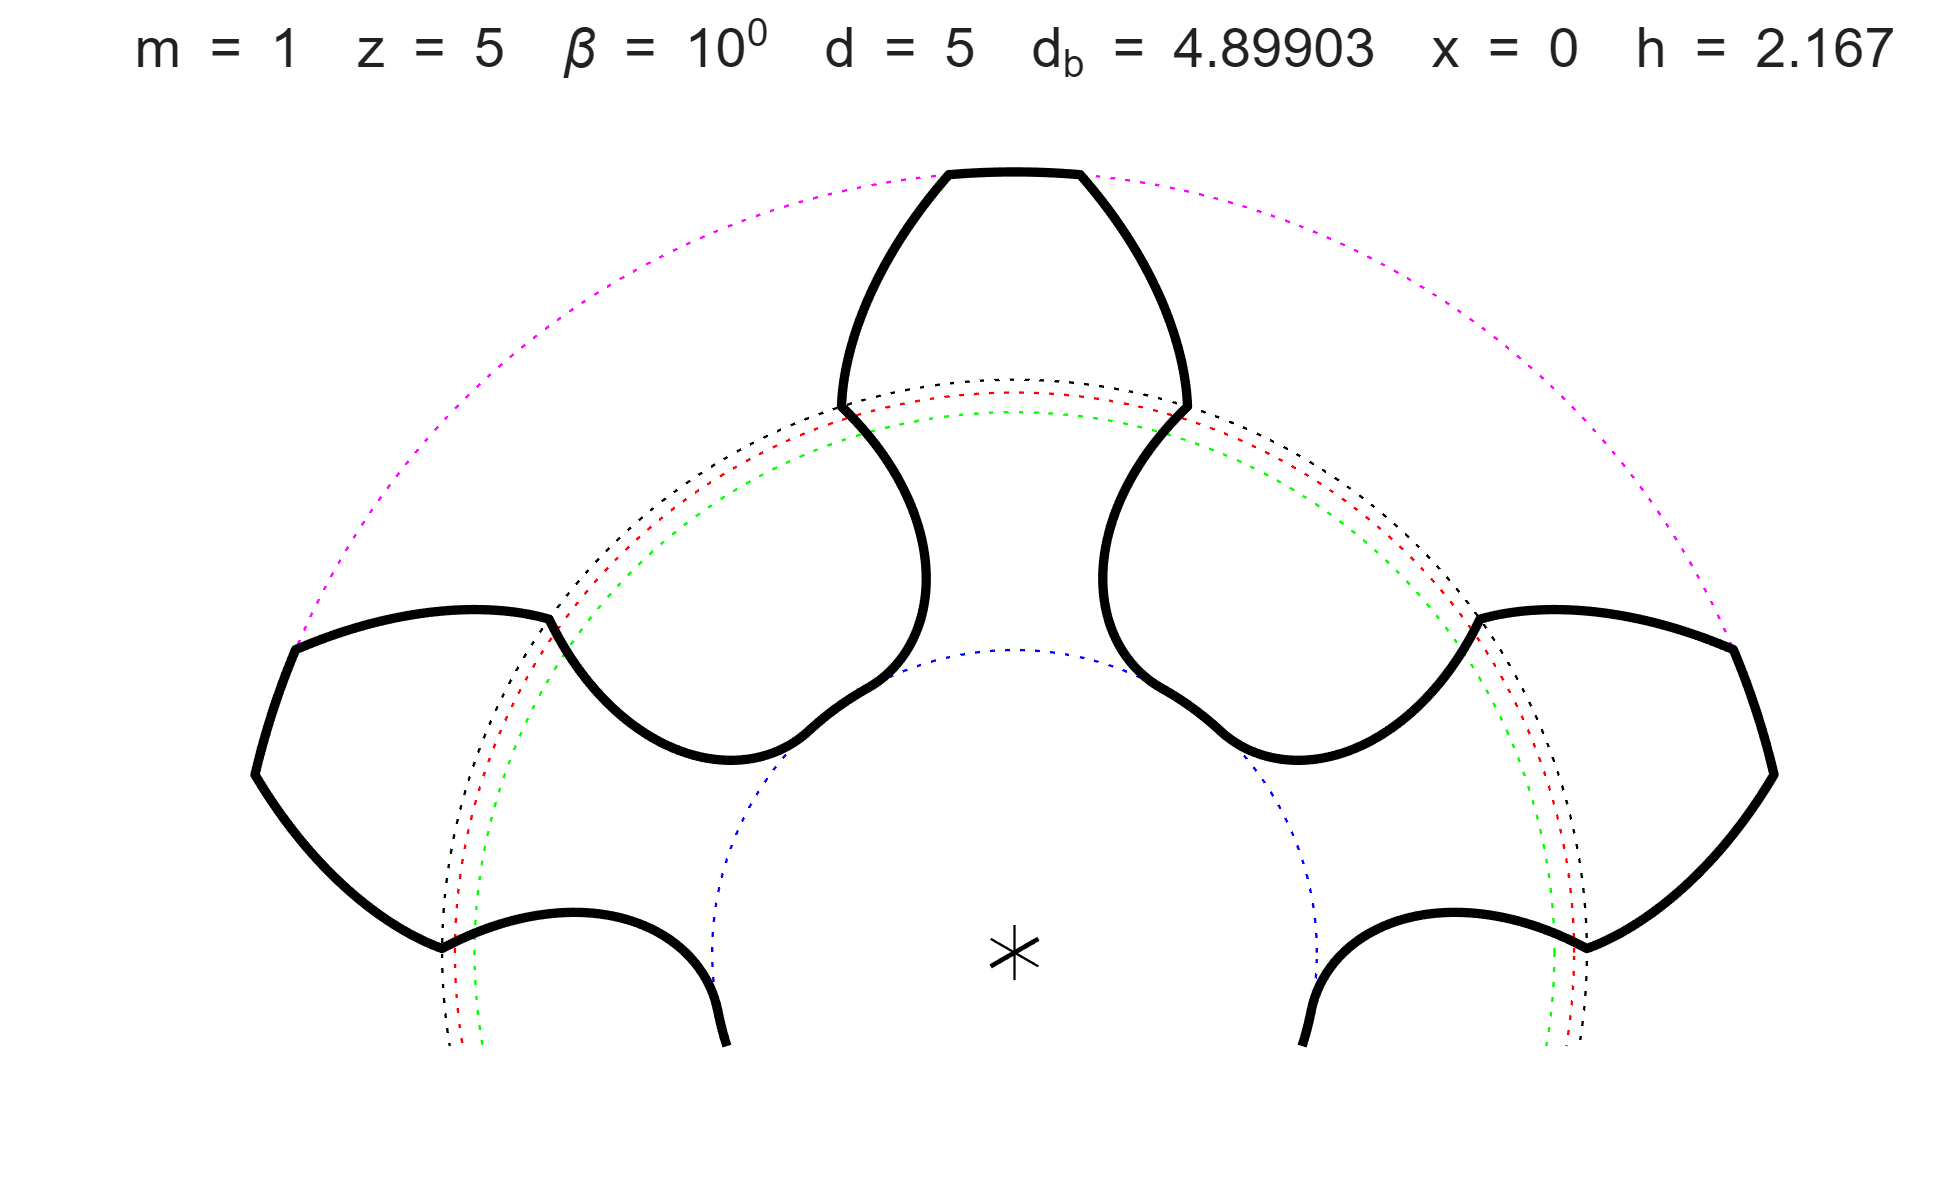

% plot 3 tooth
plot(b,'nz',3)

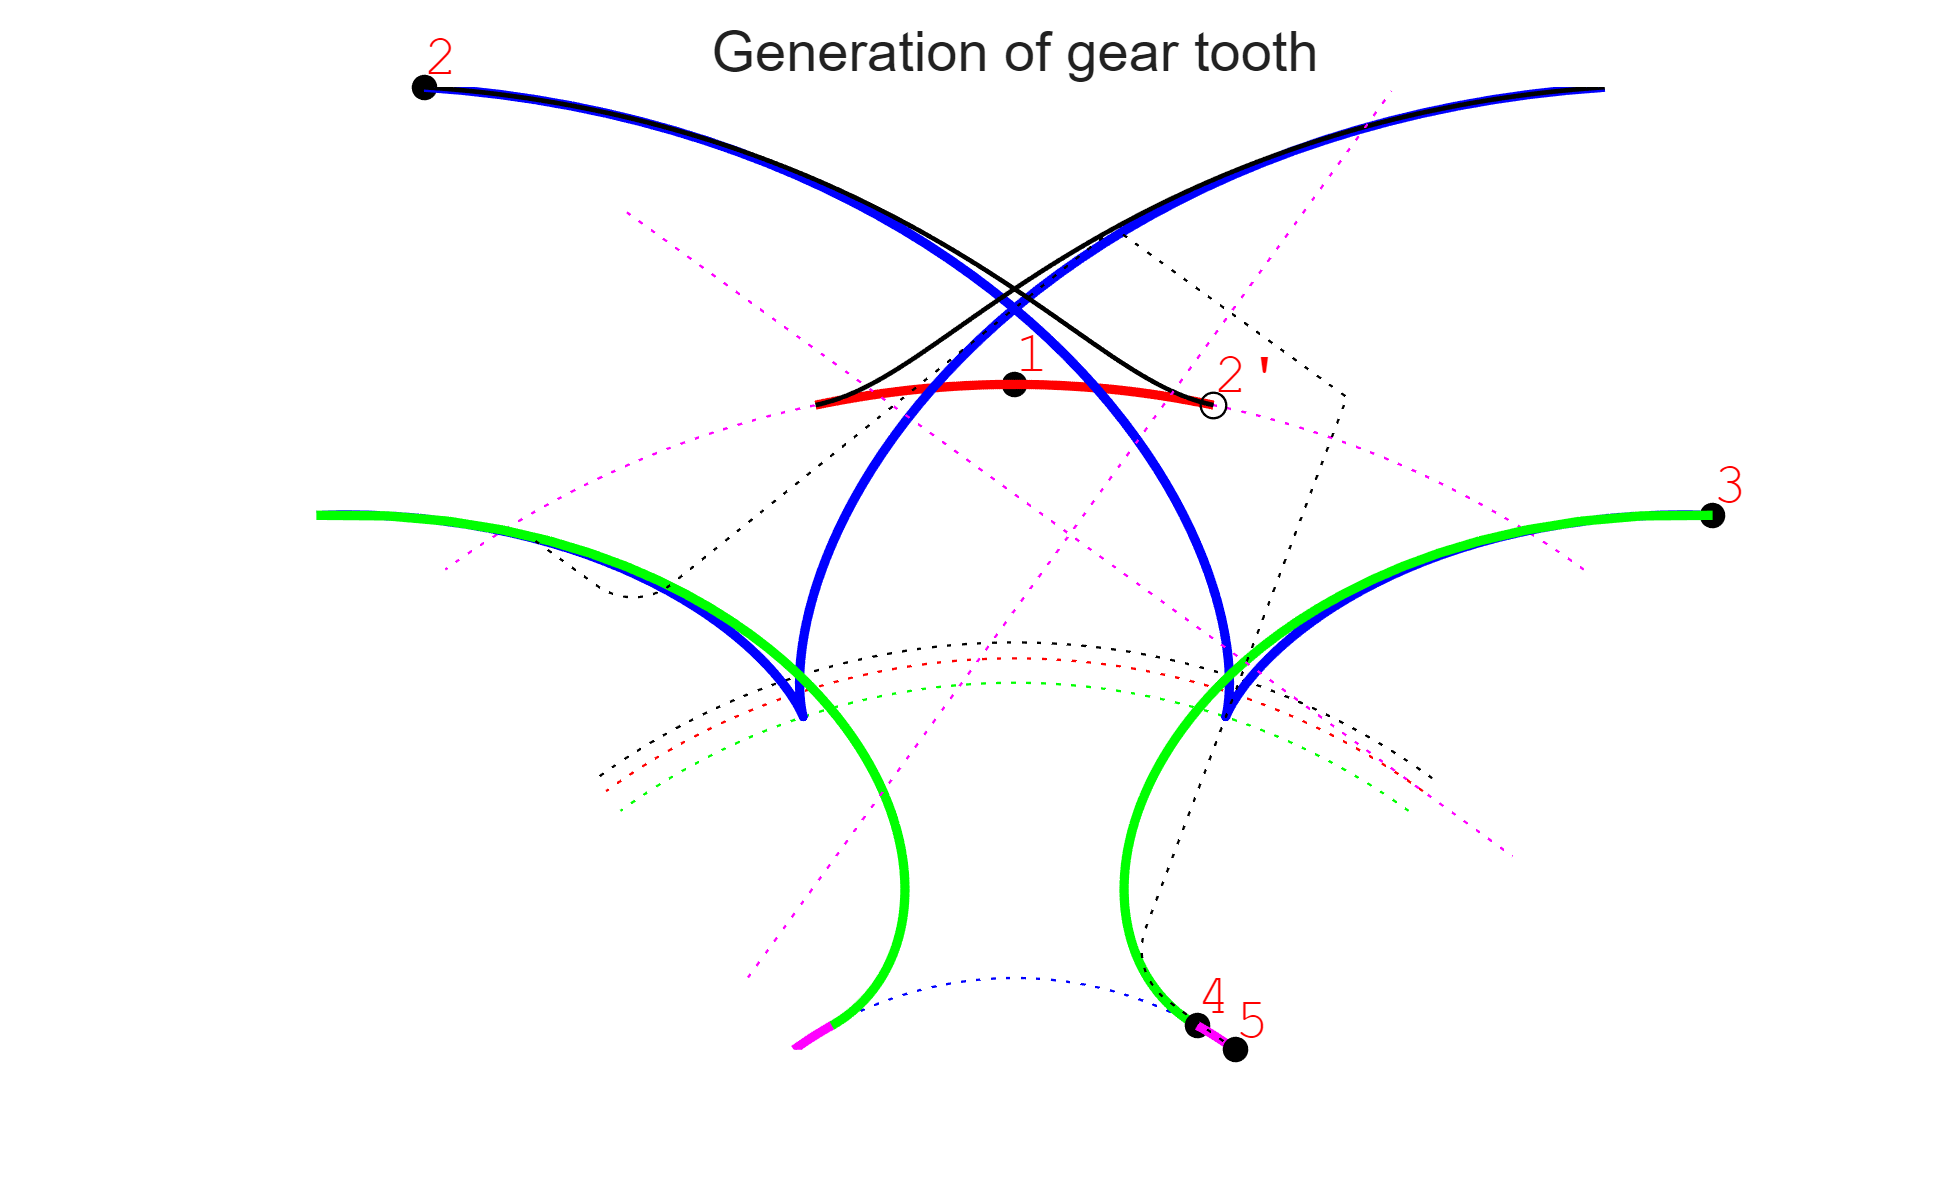

% plot gear formation
plot(b,'gen')

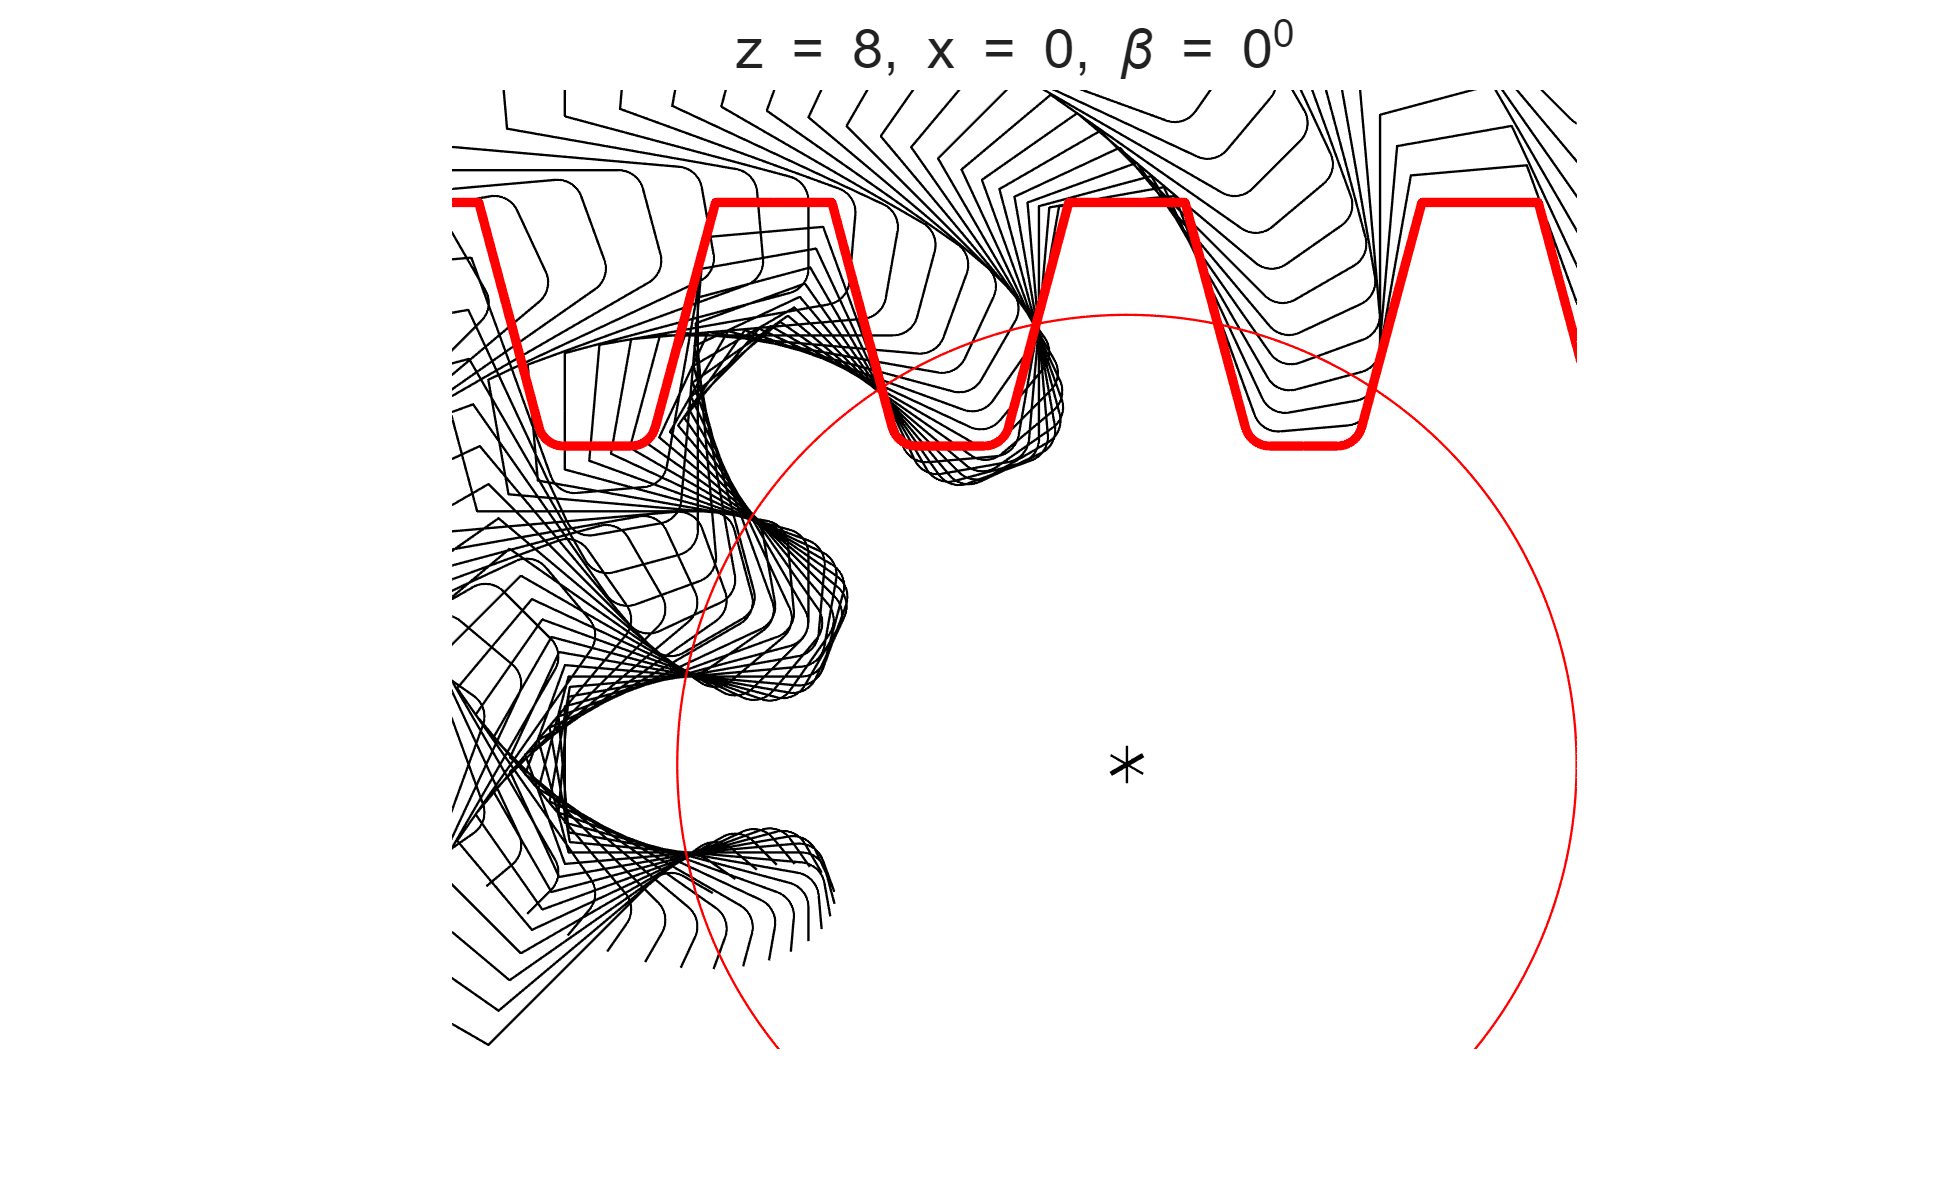

% plot gear formation by rooling rack
gearGenerating(b.rack,8)

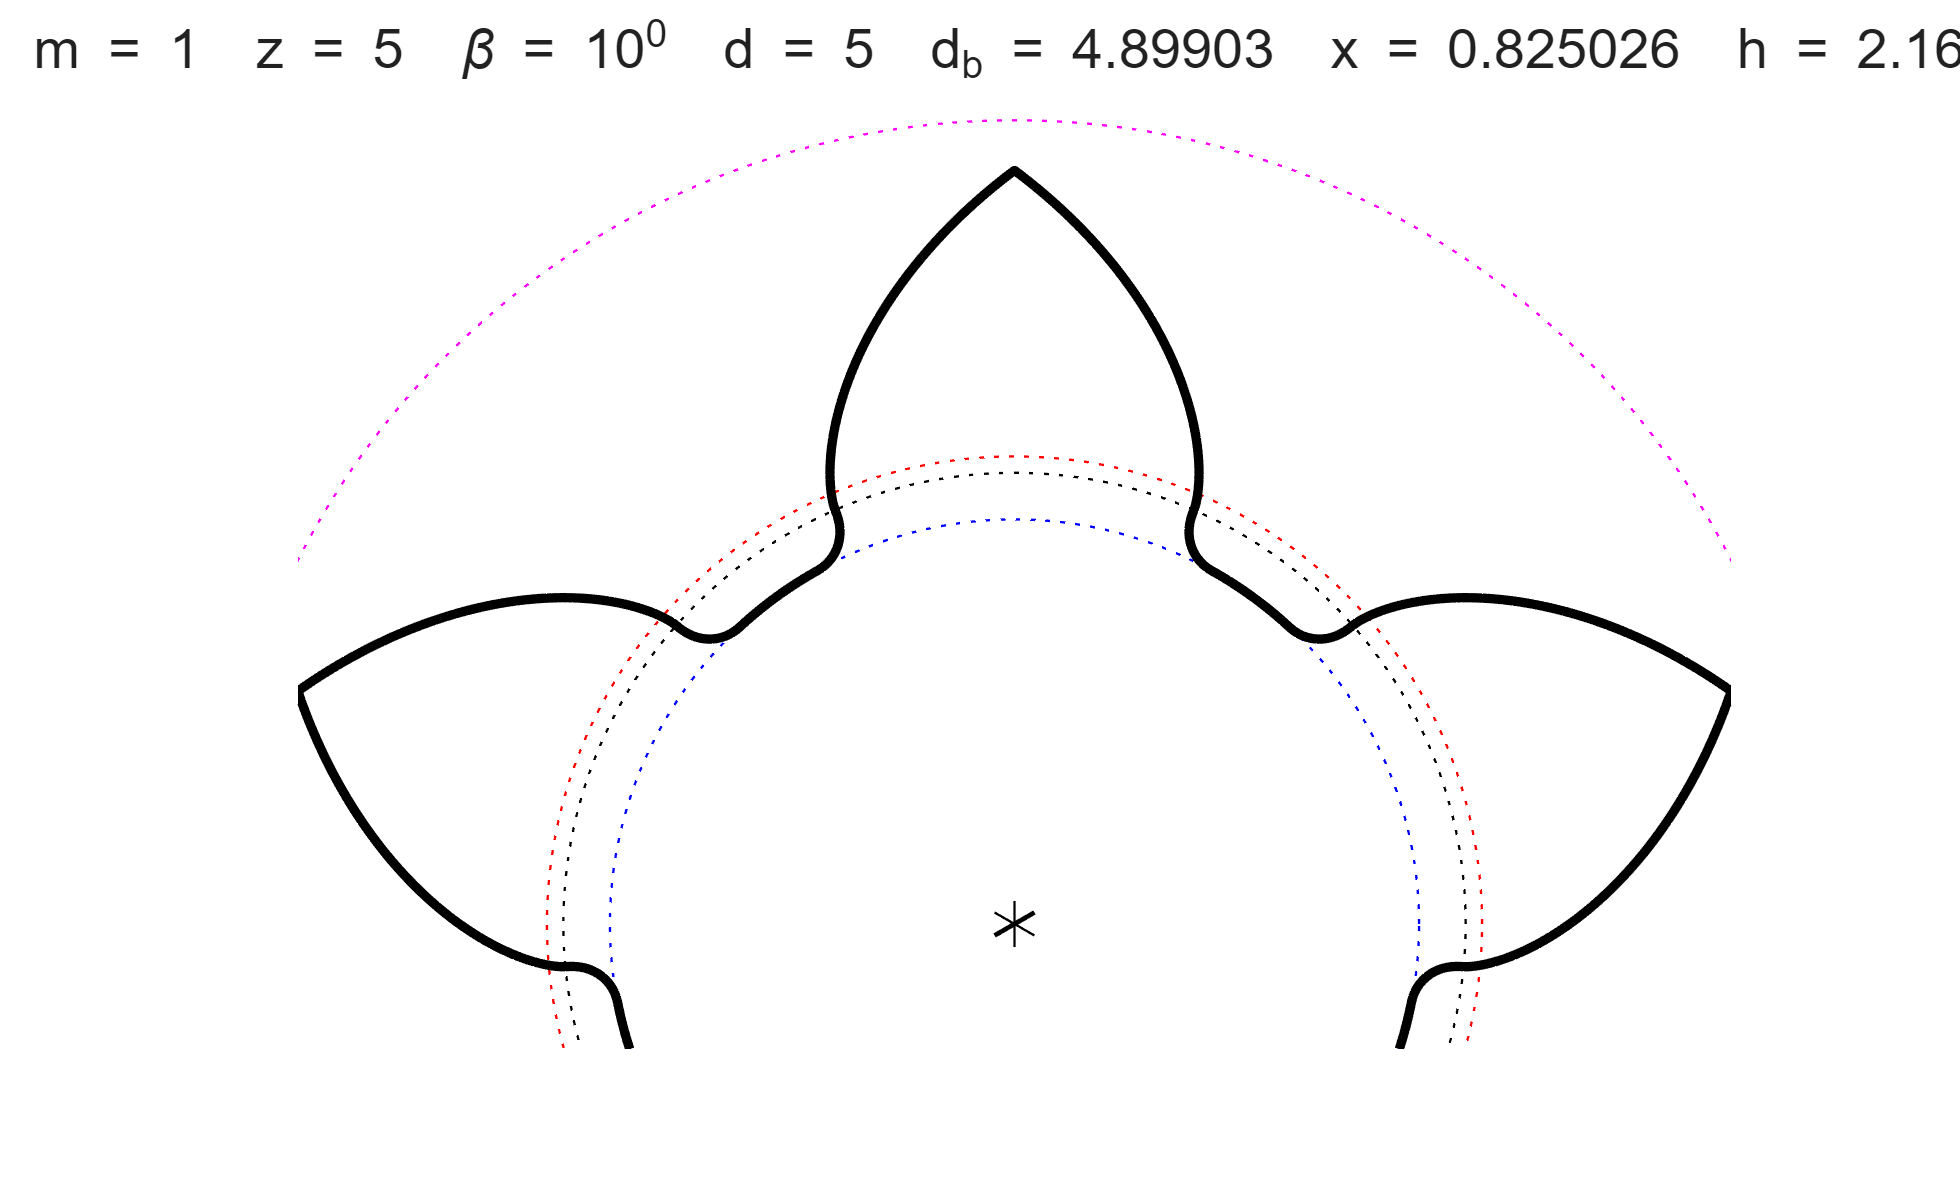

% avoid undercutting
b.x=b.xmin;
% plot three tooth
plot(b,'nz',3)

% shorten tooth height to aviod pointed teeth
b.u=0.6;
% print data
print(b)

Data
                               Number of teeth:           5
                                        Module:      1.0000 mm
                       Standard pressure angle:    15:00:00 
             Manufacturing tip tooth clearance:      0.1670 mm
                The tip shortening coefficient:      0.6000 
                                   Helix angle:    10:00:00 
                    Profile shift coefficients:      0.8250
Calculated parameters
                Addendum (tip) circle diameter:      7.9272 mm
               Reference pitch circle diameter:      5.0771 mm
                      Undercut circle diameter:      4.8990 mm
                          Base circle diameter:      4.8990 mm
               Dedendum (root) circle diameter:      4.3932 mm
                            Total tooth height:      1.7670 mm
                         Addendum tooth height:      1.4250 mm
                         Dedendum tooth height:      0.0890 mm
        Tooth thickness at the addendum 

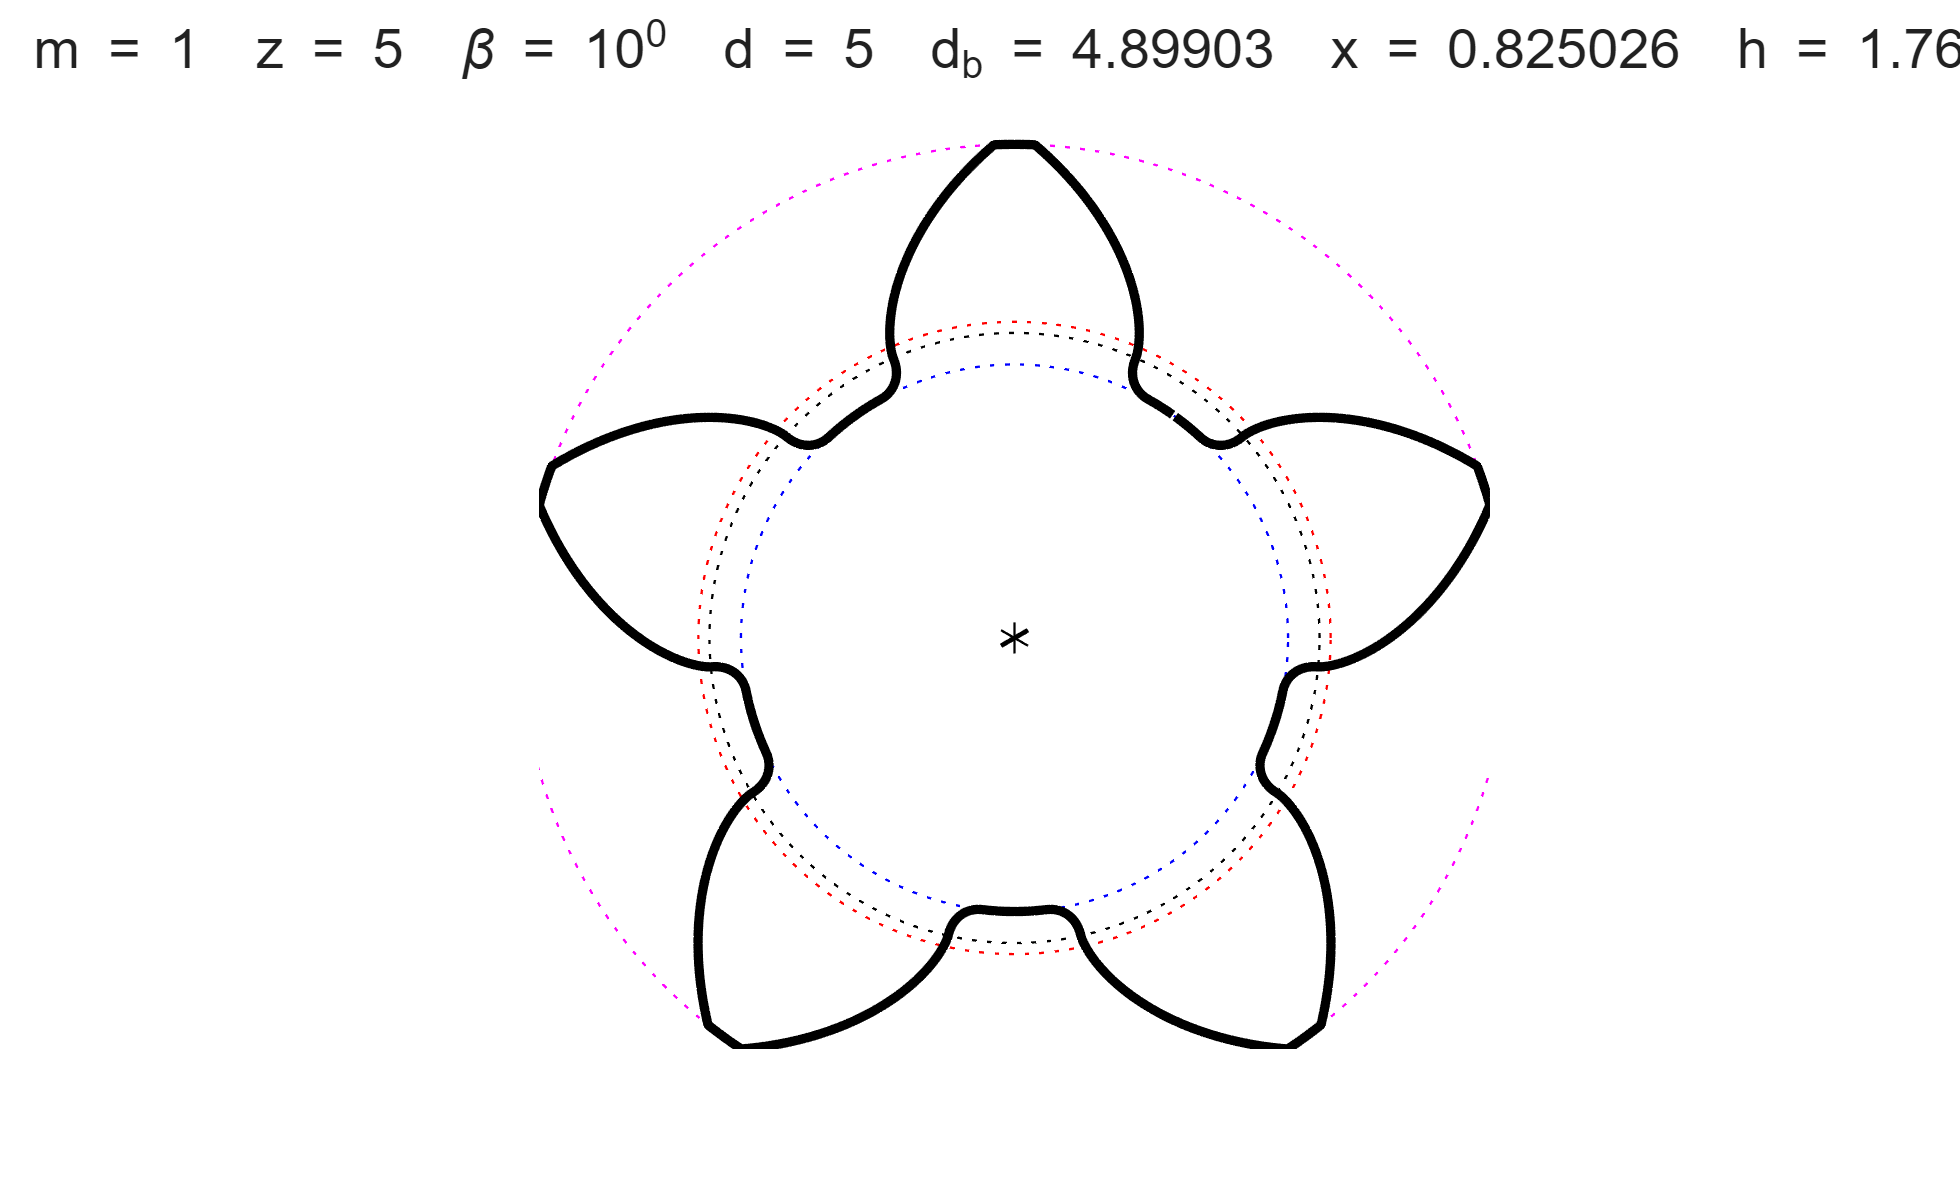

% plot gear
plot(b)

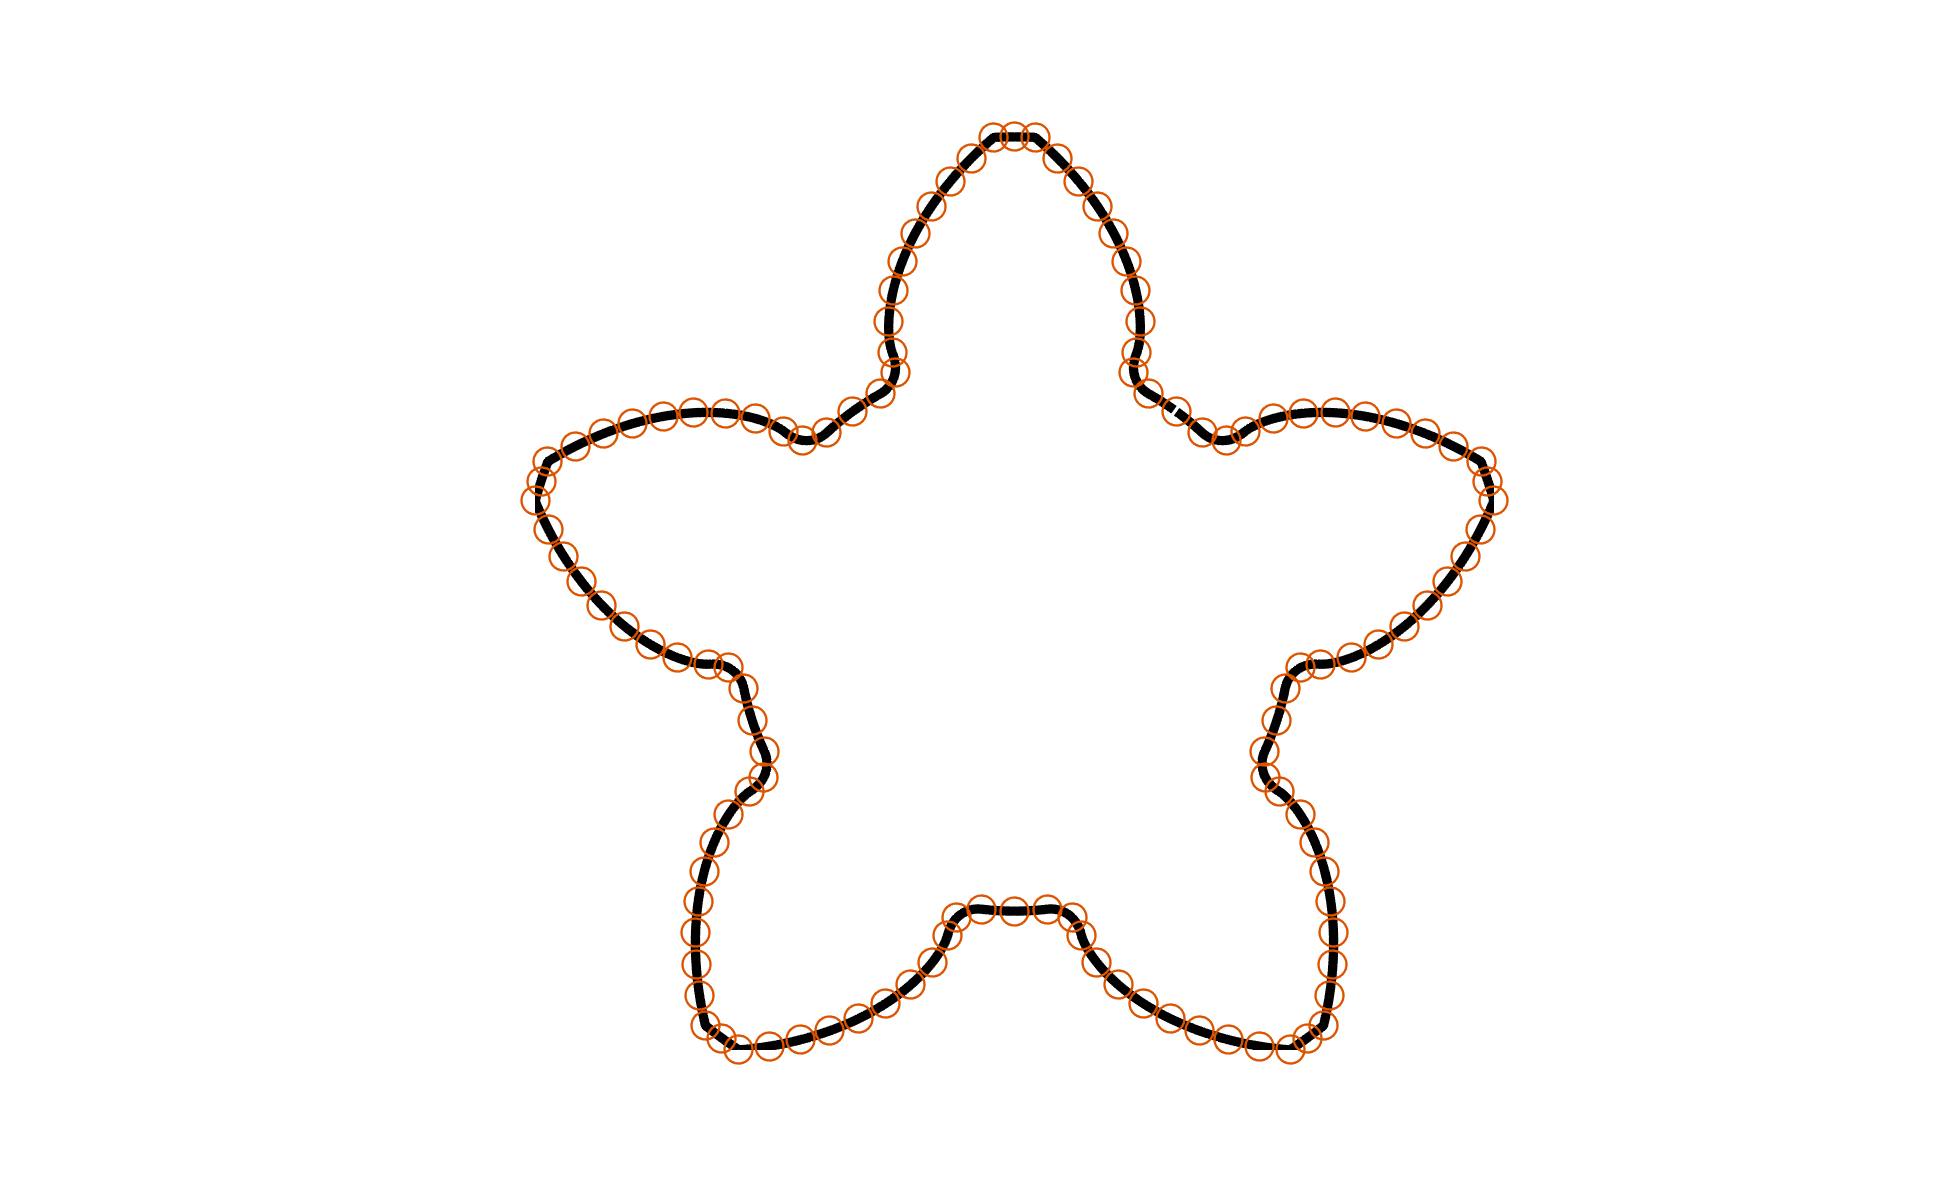

% generate contour with 10 points on profile
[x,y] = gearContour(b,'-np',10);
plot(b,'nocir','nocen','notxt') % no circles, no center no title
scatter(x,y)

### Example 3

plot(b,'nz',3)
t = 0.3; % parameter coordinate
s = getData(b,t)

s = struct with fields:
        t: 0.6421
        R: 3.2799
        X: 0.7990
        Y: 3.1811
      phi: 14.0985
        s: 1.6142
       th: 41.6845
    invth: 9.3364
        L: 2.1813


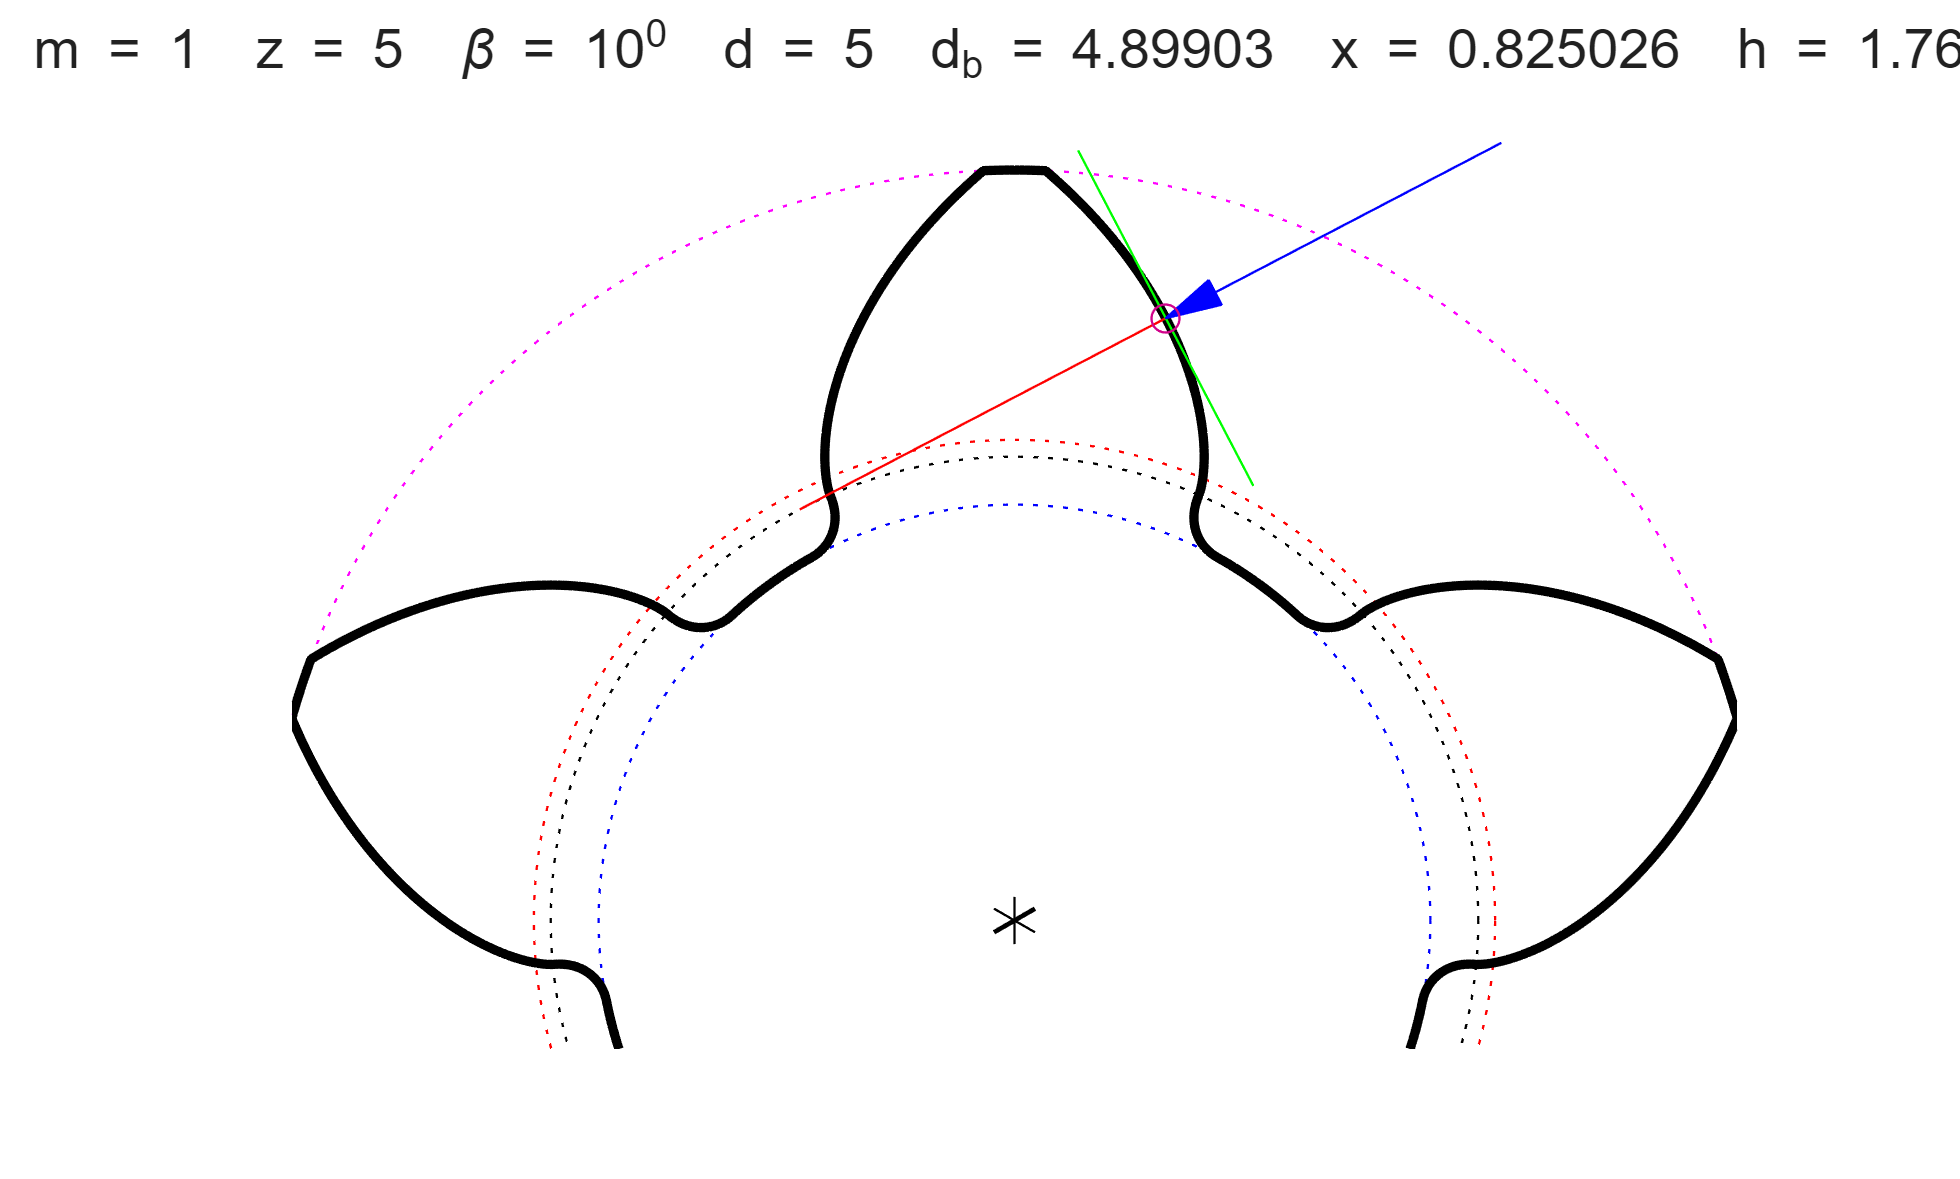

% plot normal tangen and force on gear tooth
plotNormal(b,t,-2,s.L,'r');
plotTangent(b,t,-1,1,'g');
plotForce(b,t,2,'b')
scatter(s.X,s.Y)

F = 0.3;
[X,Y,Fx,Fy,M] = getForce(b,0.3,F) %Calculate force components and moment

X = 0.7990

Y = 3.1811

Fx = -0.2659

Fy = -0.1389

M = 0.7349

%check moment
F*b.Rb

ans = 0.7349

[X,Y,Tx,Ty]=getTangent(b,0.3)  % tangent to the profile

X = 0.7990

Y = 3.1811

Tx = -0.4631

Ty = 0.8863

[X,Y,Nx,Ny]=getNormal(b,0.3)

X = 0.7990

Y = 3.1811

Nx = -0.8863

Ny = -0.4631

Nx^2+Ny^2 % check

ans = 1

Tx*Nx+Ty*Ny

ans = 0